## 1. Constitutive law + equation of motion

clear all;

%A=sym('A0',[4,4]);
syms qf qp qs C11 C13 C33 C44 C66 rho p rhof h vp vs vpf v q omega sigma13 sigma33 Ux Uz qalpha qbeta phi H lambda
kx=omega*p;
A0s=[0,i*kx,1/C44,0;
    i*kx*C13/C33,0,0,1/C33;
    kx^2*C11-kx^2*C13^2/C33-rho*omega^2,0,0,i*kx*C13/C33;
    0,-rho*omega^2,i*kx,0];
A0f=[0,kx^2*C13^2/(C33*(kx^2*C11*C33-kx^2*C13^2-rhof*omega^2*C33))+1/C33;
    -rhof*omega^2,0];
As=subs(A0s,[C11,C33,C44,C13],[rho*vp^2,rho*vp^2,rho*vs^2,vp^2*rho-2*vs^2*rho])

$$As = \begin{array}{l} \left(\begin{array}{cccc} 0 & \omega \,p\,\mathrm{i} & \frac{1}{\rho \,{\mathrm{vs}}^{2}} & 0\\ \sigma_{1} & 0 & 0 & \frac{1}{\rho \,{\mathrm{vp}}^{2}}\\ \omega^{2}\,p^{2}\,\rho \,{\mathrm{vp}}^{2}-\omega^{2}\,\rho -\frac{\omega^{2}\,p^{2}\,{\sigma_{2}}^{2}}{\rho \,{\mathrm{vp}}^{2}} & 0 & 0 & \sigma_{1}\\ 0 & -\omega^{2}\,\rho & \omega \,p\,\mathrm{i} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\omega \,p\,\sigma_{2}\,\mathrm{i}}{\rho \,{\mathrm{vp}}^{2}}\\ \sigma_{2}=\rho \,{\mathrm{vp}}^{2}-2\,\rho \,{\mathrm{vs}}^{2} \end{array}$$

Af=subs(A0f,[C11,C13,C33],[rhof*vpf^2,rhof*vpf^2,rhof*vpf^2])

$$Af = \left(\begin{array}{cc} 0 & \frac{1}{\mathrm{rhof}\,{\mathrm{vpf}}^{2}}-\frac{p^{2}}{\mathrm{rhof}}\\ -\omega^{2}\,\mathrm{rhof} & 0 \end{array}\right)$$

## 2. Eigenvalue and eigenvector of A

$\Lambda$ is the diagonal matrix whose entries are the eigenvalues of A

D is the eigenvector matrix for A


$$D^{-1}AD=\Lambda$$


[Ds,Lambdas]=eig(As)

$$Ds = \begin{array}{l} \left(\begin{array}{cccc} -\frac{p\,\mathrm{i}}{\omega \,\rho \,\sigma_{5}} & -\frac{\mathrm{i}}{2\,\omega \,p\,\rho \,{\mathrm{vs}}^{2}} & -\frac{p\,\mathrm{i}}{\omega \,\rho \,\sigma_{5}} & -\frac{\mathrm{i}}{2\,\omega \,p\,\rho \,{\mathrm{vs}}^{2}}\\ \sigma_{4} & \sigma_{2} & -\sigma_{4} & -\sigma_{2}\\ -\sigma_{1} & -\sigma_{3} & \sigma_{1} & \sigma_{3}\\ 1 & 1 & 1 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{2\,\omega \,p\,{\mathrm{vs}}^{2}\,\sqrt{\left(p\,\mathrm{vp}-1\right)\,\left(p\,\mathrm{vp}+1\right)}}{\mathrm{vp}\,\left(\omega \,\mathrm{i}-2\,\omega \,p^{2}\,{\mathrm{vs}}^{2}\,\mathrm{i}\right)}\\ \sigma_{2}=\frac{\sqrt{\left(p\,\mathrm{vs}-1\right)\,\left(p\,\mathrm{vs}+1\right)}}{2\,\omega \,\rho \,\mathrm{vs}\,\left(p^{2}\,{\mathrm{vs}}^{2}-1\right)}\\ \sigma_{3}=\frac{\omega \,\sigma_{5}\,\sqrt{\left(p\,\mathrm{vs}-1\right)\,\left(p\,\mathrm{vs}+1\right)}}{2\,\mathrm{vs}\,\left(\omega \,p\,\mathrm{i}-\omega \,p^{3}\,{\mathrm{vs}}^{2}\,\mathrm{i}\right)}\\ \sigma_{4}=\frac{\sqrt{\left(p\,\mathrm{vp}-1\right)\,\left(p\,\mathrm{vp}+1\right)}}{\omega \,\rho \,\mathrm{vp}\,\sigma_{5}}\\ \sigma_{5}=2\,p^{2}\,{\mathrm{vs}}^{2}-1 \end{array}$$

$$Lambdas = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & 0 & 0 & 0\\ 0 & \sigma_{1} & 0 & 0\\ 0 & 0 & -\sigma_{2} & 0\\ 0 & 0 & 0 & -\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\omega \,\sqrt{\left(p\,\mathrm{vs}-1\right)\,\left(p\,\mathrm{vs}+1\right)}}{\mathrm{vs}}\\ \sigma_{2}=\frac{\omega \,\sqrt{\left(p\,\mathrm{vp}-1\right)\,\left(p\,\mathrm{vp}+1\right)}}{\mathrm{vp}} \end{array}$$

[Df,Lambdaf]=eig(Af)

$$Df = \left(\begin{array}{cc} -\frac{\sqrt{\left(p\,\mathrm{vpf}-1\right)\,\left(p\,\mathrm{vpf}+1\right)}}{\omega \,\mathrm{rhof}\,\mathrm{vpf}} & \frac{\sqrt{\left(p\,\mathrm{vpf}-1\right)\,\left(p\,\mathrm{vpf}+1\right)}}{\omega \,\mathrm{rhof}\,\mathrm{vpf}}\\ 1 & 1 \end{array}\right)$$

$$Lambdaf = \left(\begin{array}{cc} \frac{\omega \,\sqrt{\left(p\,\mathrm{vpf}-1\right)\,\left(p\,\mathrm{vpf}+1\right)}}{\mathrm{vpf}} & 0\\ 0 & -\frac{\omega \,\sqrt{\left(p\,\mathrm{vpf}-1\right)\,\left(p\,\mathrm{vpf}+1\right)}}{\mathrm{vpf}} \end{array}\right)$$

aa=expm(h*Lambdaf)

$$aa = \left(\begin{array}{cc} {\mathrm{e}}^{\frac{h\,\omega \,\sqrt{\left(p\,\mathrm{vpf}-1\right)\,\left(p\,\mathrm{vpf}+1\right)}}{\mathrm{vpf}}} & 0\\ 0 & {\mathrm{e}}^{-\frac{h\,\omega \,\sqrt{\left(p\,\mathrm{vpf}-1\right)\,\left(p\,\mathrm{vpf}+1\right)}}{\mathrm{vpf}}} \end{array}\right)$$

aa2=simplify(subs(aa,vpf,sqrt(1/(qf^2+p^2))),'IgnoreAnalyticConstraints',1)

$$aa2 = \left(\begin{array}{cc} {\mathrm{e}}^{h\,\omega \,\mathrm{qf}\,\mathrm{i}} & 0\\ 0 & {\mathrm{e}}^{-h\,\omega \,\mathrm{qf}\,\mathrm{i}} \end{array}\right)$$

aa3=expm(h*Lambdas)

$$aa3 = \begin{array}{l} \left(\begin{array}{cccc} {\mathrm{e}}^{\sigma_{2}} & 0 & 0 & 0\\ 0 & {\mathrm{e}}^{\sigma_{1}} & 0 & 0\\ 0 & 0 & {\mathrm{e}}^{-\sigma_{2}} & 0\\ 0 & 0 & 0 & {\mathrm{e}}^{-\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{h\,\omega \,\sqrt{\left(p\,\mathrm{vs}-1\right)\,\left(p\,\mathrm{vs}+1\right)}}{\mathrm{vs}}\\ \sigma_{2}=\frac{h\,\omega \,\sqrt{\left(p\,\mathrm{vp}-1\right)\,\left(p\,\mathrm{vp}+1\right)}}{\mathrm{vp}} \end{array}$$

aa4=simplify(subs(aa3,[vp,vs],[sqrt(1/(qp^2+p^2)),sqrt(1/(qs^2+p^2))]),'IgnoreAnalyticConstraints',1)

$$aa4 = \left(\begin{array}{cccc} {\mathrm{e}}^{h\,\omega \,\mathrm{qp}\,\mathrm{i}} & 0 & 0 & 0\\ 0 & {\mathrm{e}}^{h\,\omega \,\mathrm{qs}\,\mathrm{i}} & 0 & 0\\ 0 & 0 & {\mathrm{e}}^{-h\,\omega \,\mathrm{qp}\,\mathrm{i}} & 0\\ 0 & 0 & 0 & {\mathrm{e}}^{-h\,\omega \,\mathrm{qs}\,\mathrm{i}} \end{array}\right)$$

Ps=expm((1-phi)*H*As)

Pf=expm(phi*H*Af)

$$Pf = \begin{array}{l} \left(\begin{array}{cc} \sigma_{1} & -\frac{\sigma_{3}\,\sqrt{\left(p\,\mathrm{vpf}-1\right)\,\left(p\,\mathrm{vpf}+1\right)}-\sigma_{2}\,\sqrt{\left(p\,\mathrm{vpf}-1\right)\,\left(p\,\mathrm{vpf}+1\right)}}{2\,\omega \,\mathrm{rhof}\,\mathrm{vpf}}\\ -\frac{\omega \,\mathrm{rhof}\,\mathrm{vpf}\,\sigma_{3}-\omega \,\mathrm{rhof}\,\mathrm{vpf}\,\sigma_{2}}{2\,\sqrt{\left(p\,\mathrm{vpf}-1\right)\,\left(p\,\mathrm{vpf}+1\right)}} & \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sigma_{3}}{2}+\frac{\sigma_{2}}{2}\\ \sigma_{2}={\mathrm{e}}^{-\frac{H\,\omega \,\phi \,\sqrt{\left(p\,\mathrm{vpf}-1\right)\,\left(p\,\mathrm{vpf}+1\right)}}{\mathrm{vpf}}}\\ \sigma_{3}={\mathrm{e}}^{\frac{H\,\omega \,\phi \,\sqrt{\left(p\,\mathrm{vpf}-1\right)\,\left(p\,\mathrm{vpf}+1\right)}}{\mathrm{vpf}}} \end{array}$$

Qs=[-Ps(2,1)*Ps(3,2)/Ps(3,1)+Ps(2,2),-Ps(2,1)*Ps(3,4)/Ps(3,1)+Ps(2,4);
    -Ps(4,1)*Ps(3,2)/Ps(3,1)+Ps(4,2),-Ps(4,1)*Ps(3,4)/Ps(3,1)+Ps(4,4)];
M=Pf*Qs;
M2=vpa(subs(M,[H,vp,vs,rho,vpf,rhof,omega,phi,p],...
        [1,4000,2200,2700,1500,1000,5,.1,10^-5]))

$$M2 = \left(\begin{array}{cc} 0.99999661241085387588582582937641 & 0.000000000065262535428444793780621562847147+7.1630090251916576854021836438212\,10^{-49}\,\mathrm{i}\\ -63249.982206527783610348496609837 & 0.99999925973243379971939693931828-1.7907523226071520729590318536276\,10^{-45}\,\mathrm{i} \end{array}\right)$$

## 3. Formulate the equation for M

eq=cos(omega*q*H)==trace(M)/2

qa=solve(eq,q)

qa2=simplify(qa,'IgnoreAnalyticConstraints',1)

## 4. Numerical test

same model with Korneev (2011).

p0=10^-5:10^-6:6*10^-3;
H=1;
vp=4000;
vs=2200;
rho=2700;
vpf=1500;
rhof=1000;
omega=2*pi*10;
phi=.001;
p=p0;
%q0=acos(cosh((H.*omega.*phi.*(p.^2.*vpf.^2 - 1).^(1./2))./vpf).*(exp(-(H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp)./2 - exp((H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp)./2 + exp((H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs) - p.^2.*vs.^2.*exp(-(H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp) + p.^2.*vs.^2.*exp(-(H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs) - (exp((H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp) - exp((H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs)).*(p.*vs - 1).*(p.*vs + 1) + (omega.*p.*rho.*vs.^2.*exp(-(H.*omega.*(vp.*(p.^2.*vs.^2 - 1).^(1./2) + vs.*(p.^2.*vp.^2 - 1).^(1./2)).*(phi - 1))./(vp.*vs)).*(2.*p.^2.*vs.^2 - 1).*(exp((H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp) - exp((H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs) - exp((H.*omega.*(vp.*(p.^2.*vs.^2 - 1).^(1./2) + 2.*vs.*(p.^2.*vp.^2 - 1).^(1./2)).*(phi - 1))./(vp.*vs)) + exp((H.*omega.*(2.*vp.*(p.^2.*vs.^2 - 1).^(1./2) + vs.*(p.^2.*vp.^2 - 1).^(1./2)).*(phi - 1))./(vp.*vs))).*(2.*p.^3.*vs.^4.*exp((H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp).*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2) - 2.*p.^3.*vs.^4.*exp(-(H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp).*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2) - 2.*p.*vs.^2.*exp((H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp).*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2) + 2.*p.*vs.^2.*exp(-(H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp).*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2) - p.*vp.*vs.*exp((H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2) + p.*vp.*vs.*exp(-(H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2) - 2.*p.*vp.*vs.*exp((H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vs - 1).^(3./2).*(p.*vs + 1).^(3./2) + 2.*p.*vp.*vs.*exp(-(H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vs - 1).^(3./2).*(p.*vs + 1).^(3./2)))./(4.*omega.*p.^2.*rho.*vs.^4.*exp((H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp).*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2) - 4.*omega.*p.^2.*rho.*vs.^4.*exp(-(H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp).*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2) - 4.*omega.*p.^4.*rho.*vs.^6.*exp((H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp).*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2) + 4.*omega.*p.^4.*rho.*vs.^6.*exp(-(H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp).*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2) + omega.*rho.*vp.*vs.*exp((H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2) - omega.*rho.*vp.*vs.*exp(-(H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2) + 4.*omega.*rho.*vp.*vs.*exp((H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vs - 1).^(3./2).*(p.*vs + 1).^(3./2) - 4.*omega.*rho.*vp.*vs.*exp(-(H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vs - 1).^(3./2).*(p.*vs + 1).^(3./2) + 4.*omega.*rho.*vp.*vs.*exp((H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vs - 1).^(5./2).*(p.*vs + 1).^(5./2) - 4.*omega.*rho.*vp.*vs.*exp(-(H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vs - 1).^(5./2).*(p.*vs + 1).^(5./2))) - (sinh((H.*omega.*phi.*(p.^2.*vpf.^2 - 1).^(1./2))./vpf).*(p.^2.*vpf.^2 - 1).^(1./2).*((omega.*rho.*vp.*exp((H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp).*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2) - omega.*rho.*vp.*exp(-(H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp).*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2) + 4.*omega.*rho.*vp.*exp((H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp).*(p.*vs - 1).^(3./2).*(p.*vs + 1).^(3./2) - 4.*omega.*rho.*vp.*exp(-(H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp).*(p.*vs - 1).^(3./2).*(p.*vs + 1).^(3./2) + 4.*omega.*rho.*vp.*exp((H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp).*(p.*vs - 1).^(5./2).*(p.*vs + 1).^(5./2) - 4.*omega.*rho.*vp.*exp(-(H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp).*(p.*vs - 1).^(5./2).*(p.*vs + 1).^(5./2) + 4.*omega.*p.^2.*rho.*vs.^3.*exp((H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2) - 4.*omega.*p.^2.*rho.*vs.^3.*exp(-(H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2) - 4.*omega.*p.^4.*rho.*vs.^5.*exp((H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2) + 4.*omega.*p.^4.*rho.*vs.^5.*exp(-(H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2))./(2.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2)) + (2.*omega.^2.*p.^2.*rho.^2.*vp.*vs.^4.*exp(-(2.*H.*omega.*(vp.*(p.^2.*vs.^2 - 1).^(1./2) + vs.*(p.^2.*vp.^2 - 1).^(1./2)).*(phi - 1))./(vp.*vs)).*(p.^2.*vs.^2 - 1).*(2.*p.^2.*vs.^2 - 1).^2.*(exp((H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp) - exp((H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs) - exp((H.*omega.*(vp.*(p.^2.*vs.^2 - 1).^(1./2) + 2.*vs.*(p.^2.*vp.^2 - 1).^(1./2)).*(phi - 1))./(vp.*vs)) + exp((H.*omega.*(2.*vp.*(p.^2.*vs.^2 - 1).^(1./2) + vs.*(p.^2.*vp.^2 - 1).^(1./2)).*(phi - 1))./(vp.*vs))).^2)./(4.*omega.*p.^2.*rho.*vs.^4.*exp((H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp).*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2) - 4.*omega.*p.^2.*rho.*vs.^4.*exp(-(H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp).*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2) - 4.*omega.*p.^4.*rho.*vs.^6.*exp((H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp).*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2) + 4.*omega.*p.^4.*rho.*vs.^6.*exp(-(H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp).*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2) + omega.*rho.*vp.*vs.*exp((H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2) - omega.*rho.*vp.*vs.*exp(-(H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2) + 4.*omega.*rho.*vp.*vs.*exp((H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vs - 1).^(3./2).*(p.*vs + 1).^(3./2) - 4.*omega.*rho.*vp.*vs.*exp(-(H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vs - 1).^(3./2).*(p.*vs + 1).^(3./2) + 4.*omega.*rho.*vp.*vs.*exp((H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vs - 1).^(5./2).*(p.*vs + 1).^(5./2) - 4.*omega.*rho.*vp.*vs.*exp(-(H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vs - 1).^(5./2).*(p.*vs + 1).^(5./2))))./(2.*omega.*rhof.*vpf) + (rhof.*vpf.*sinh((H.*omega.*phi.*(p.^2.*vpf.^2 - 1).^(1./2))./vpf).*(exp((2.*H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp) - 1).*(exp((2.*H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs) - 1).*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2))./(4.*rho.*(p.*vpf - 1).^(1./2).*(p.*vpf + 1).^(1./2).*(vp.*exp((H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp).*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2) + 4.*vp.*exp((H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp).*(p.*vs - 1).^(3./2).*(p.*vs + 1).^(3./2) + 4.*vp.*exp((H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp).*(p.*vs - 1).^(5./2).*(p.*vs + 1).^(5./2) - vp.*exp((H.*omega.*(2.*vp.*(p.^2.*vs.^2 - 1).^(1./2) + vs.*(p.^2.*vp.^2 - 1).^(1./2)).*(phi - 1))./(vp.*vs)).*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2) - 4.*vp.*exp((H.*omega.*(2.*vp.*(p.^2.*vs.^2 - 1).^(1./2) + vs.*(p.^2.*vp.^2 - 1).^(1./2)).*(phi - 1))./(vp.*vs)).*(p.*vs - 1).^(3./2).*(p.*vs + 1).^(3./2) - 4.*vp.*exp((H.*omega.*(2.*vp.*(p.^2.*vs.^2 - 1).^(1./2) + vs.*(p.^2.*vp.^2 - 1).^(1./2)).*(phi - 1))./(vp.*vs)).*(p.*vs - 1).^(5./2).*(p.*vs + 1).^(5./2) + 4.*p.^2.*vs.^3.*exp((H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2) - 4.*p.^4.*vs.^5.*exp((H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2) - 4.*p.^2.*vs.^3.*exp((H.*omega.*(vp.*(p.^2.*vs.^2 - 1).^(1./2) + 2.*vs.*(p.^2.*vp.^2 - 1).^(1./2)).*(phi - 1))./(vp.*vs)).*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2) + 4.*p.^4.*vs.^5.*exp((H.*omega.*(vp.*(p.^2.*vs.^2 - 1).^(1./2) + 2.*vs.*(p.^2.*vp.^2 - 1).^(1./2)).*(phi - 1))./(vp.*vs)).*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2))))./(H.*omega);
q0=acos(cosh((H.*omega.*phi.*(p.^2.*vpf.^2 - 1).^(1./2))./vpf).*(exp(-(H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp)./2 - exp((H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp)./2 + exp((H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs) - p.^2.*vs.^2.*exp(-(H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp) + p.^2.*vs.^2.*exp(-(H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs) - (exp((H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp) - exp((H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs)).*(p.*vs - 1).*(p.*vs + 1) + (omega.*p.*rho.*vs.^2.*exp(-(H.*omega.*(vp.*(p.^2.*vs.^2 - 1).^(1./2) + vs.*(p.^2.*vp.^2 - 1).^(1./2)).*(phi - 1))./(vp.*vs)).*(2.*p.^2.*vs.^2 - 1).*(exp((H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp) - exp((H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs) - exp((H.*omega.*(vp.*(p.^2.*vs.^2 - 1).^(1./2) + 2.*vs.*(p.^2.*vp.^2 - 1).^(1./2)).*(phi - 1))./(vp.*vs)) + exp((H.*omega.*(2.*vp.*(p.^2.*vs.^2 - 1).^(1./2) + vs.*(p.^2.*vp.^2 - 1).^(1./2)).*(phi - 1))./(vp.*vs))).*(2.*p.^3.*vs.^4.*exp((H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp).*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2) - 2.*p.^3.*vs.^4.*exp(-(H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp).*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2) - 2.*p.*vs.^2.*exp((H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp).*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2) + 2.*p.*vs.^2.*exp(-(H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp).*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2) - p.*vp.*vs.*exp((H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2) + p.*vp.*vs.*exp(-(H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2) - 2.*p.*vp.*vs.*exp((H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vs - 1).^(3./2).*(p.*vs + 1).^(3./2) + 2.*p.*vp.*vs.*exp(-(H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vs - 1).^(3./2).*(p.*vs + 1).^(3./2)))./(4.*omega.*p.^2.*rho.*vs.^4.*exp((H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp).*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2) - 4.*omega.*p.^2.*rho.*vs.^4.*exp(-(H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp).*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2) - 4.*omega.*p.^4.*rho.*vs.^6.*exp((H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp).*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2) + 4.*omega.*p.^4.*rho.*vs.^6.*exp(-(H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp).*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2) + omega.*rho.*vp.*vs.*exp((H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2) - omega.*rho.*vp.*vs.*exp(-(H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2) + 4.*omega.*rho.*vp.*vs.*exp((H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vs - 1).^(3./2).*(p.*vs + 1).^(3./2) - 4.*omega.*rho.*vp.*vs.*exp(-(H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vs - 1).^(3./2).*(p.*vs + 1).^(3./2) + 4.*omega.*rho.*vp.*vs.*exp((H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vs - 1).^(5./2).*(p.*vs + 1).^(5./2) - 4.*omega.*rho.*vp.*vs.*exp(-(H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vs - 1).^(5./2).*(p.*vs + 1).^(5./2))) - (sinh((H.*omega.*phi.*(p.^2.*vpf.^2 - 1).^(1./2))./vpf).*(p.^2.*vpf.^2 - 1).^(1./2).*((omega.*rho.*vp.*exp((H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp).*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2) - omega.*rho.*vp.*exp(-(H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp).*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2) + 4.*omega.*rho.*vp.*exp((H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp).*(p.*vs - 1).^(3./2).*(p.*vs + 1).^(3./2) - 4.*omega.*rho.*vp.*exp(-(H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp).*(p.*vs - 1).^(3./2).*(p.*vs + 1).^(3./2) + 4.*omega.*rho.*vp.*exp((H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp).*(p.*vs - 1).^(5./2).*(p.*vs + 1).^(5./2) - 4.*omega.*rho.*vp.*exp(-(H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp).*(p.*vs - 1).^(5./2).*(p.*vs + 1).^(5./2) + 4.*omega.*p.^2.*rho.*vs.^3.*exp((H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2) - 4.*omega.*p.^2.*rho.*vs.^3.*exp(-(H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2) - 4.*omega.*p.^4.*rho.*vs.^5.*exp((H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2) + 4.*omega.*p.^4.*rho.*vs.^5.*exp(-(H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2))./(2.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2)) + (2.*omega.^2.*p.^2.*rho.^2.*vp.*vs.^4.*exp(-(2.*H.*omega.*(vp.*(p.^2.*vs.^2 - 1).^(1./2) + vs.*(p.^2.*vp.^2 - 1).^(1./2)).*(phi - 1))./(vp.*vs)).*(p.^2.*vs.^2 - 1).*(2.*p.^2.*vs.^2 - 1).^2.*(exp((H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp) - exp((H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs) - exp((H.*omega.*(vp.*(p.^2.*vs.^2 - 1).^(1./2) + 2.*vs.*(p.^2.*vp.^2 - 1).^(1./2)).*(phi - 1))./(vp.*vs)) + exp((H.*omega.*(2.*vp.*(p.^2.*vs.^2 - 1).^(1./2) + vs.*(p.^2.*vp.^2 - 1).^(1./2)).*(phi - 1))./(vp.*vs))).^2)./(4.*omega.*p.^2.*rho.*vs.^4.*exp((H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp).*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2) - 4.*omega.*p.^2.*rho.*vs.^4.*exp(-(H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp).*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2) - 4.*omega.*p.^4.*rho.*vs.^6.*exp((H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp).*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2) + 4.*omega.*p.^4.*rho.*vs.^6.*exp(-(H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp).*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2) + omega.*rho.*vp.*vs.*exp((H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2) - omega.*rho.*vp.*vs.*exp(-(H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2) + 4.*omega.*rho.*vp.*vs.*exp((H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vs - 1).^(3./2).*(p.*vs + 1).^(3./2) - 4.*omega.*rho.*vp.*vs.*exp(-(H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vs - 1).^(3./2).*(p.*vs + 1).^(3./2) + 4.*omega.*rho.*vp.*vs.*exp((H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vs - 1).^(5./2).*(p.*vs + 1).^(5./2) - 4.*omega.*rho.*vp.*vs.*exp(-(H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vs - 1).^(5./2).*(p.*vs + 1).^(5./2))))./(2.*omega.*rhof.*vpf) + (rhof.*vpf.*sinh((H.*omega.*phi.*(p.^2.*vpf.^2 - 1).^(1./2))./vpf).*(exp((2.*H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp) - 1).*(exp((2.*H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs) - 1).*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2))./(4.*rho.*(p.*vpf - 1).^(1./2).*(p.*vpf + 1).^(1./2).*(vp.*exp((H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp).*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2) + 4.*vp.*exp((H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp).*(p.*vs - 1).^(3./2).*(p.*vs + 1).^(3./2) + 4.*vp.*exp((H.*omega.*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2).*(phi - 1))./vp).*(p.*vs - 1).^(5./2).*(p.*vs + 1).^(5./2) - vp.*exp((H.*omega.*(2.*vp.*(p.^2.*vs.^2 - 1).^(1./2) + vs.*(p.^2.*vp.^2 - 1).^(1./2)).*(phi - 1))./(vp.*vs)).*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2) - 4.*vp.*exp((H.*omega.*(2.*vp.*(p.^2.*vs.^2 - 1).^(1./2) + vs.*(p.^2.*vp.^2 - 1).^(1./2)).*(phi - 1))./(vp.*vs)).*(p.*vs - 1).^(3./2).*(p.*vs + 1).^(3./2) - 4.*vp.*exp((H.*omega.*(2.*vp.*(p.^2.*vs.^2 - 1).^(1./2) + vs.*(p.^2.*vp.^2 - 1).^(1./2)).*(phi - 1))./(vp.*vs)).*(p.*vs - 1).^(5./2).*(p.*vs + 1).^(5./2) + 4.*p.^2.*vs.^3.*exp((H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2) - 4.*p.^4.*vs.^5.*exp((H.*omega.*(p.*vs - 1).^(1./2).*(p.*vs + 1).^(1./2).*(phi - 1))./vs).*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2) - 4.*p.^2.*vs.^3.*exp((H.*omega.*(vp.*(p.^2.*vs.^2 - 1).^(1./2) + 2.*vs.*(p.^2.*vp.^2 - 1).^(1./2)).*(phi - 1))./(vp.*vs)).*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2) + 4.*p.^4.*vs.^5.*exp((H.*omega.*(vp.*(p.^2.*vs.^2 - 1).^(1./2) + 2.*vs.*(p.^2.*vp.^2 - 1).^(1./2)).*(phi - 1))./(vp.*vs)).*(p.*vp - 1).^(1./2).*(p.*vp + 1).^(1./2))))./(H.*omega);

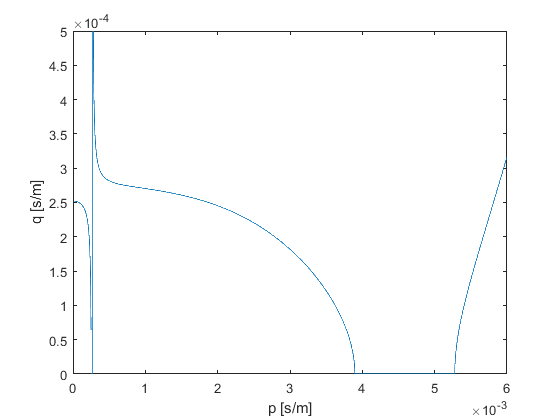

plot(p0,real(q0));
xlabel('p [s/m]');
ylabel('q [s/m]');
ylim([0,.5*10^-3]);
print(gcf,['Korneev2011.png'],'-dpng','-r600');